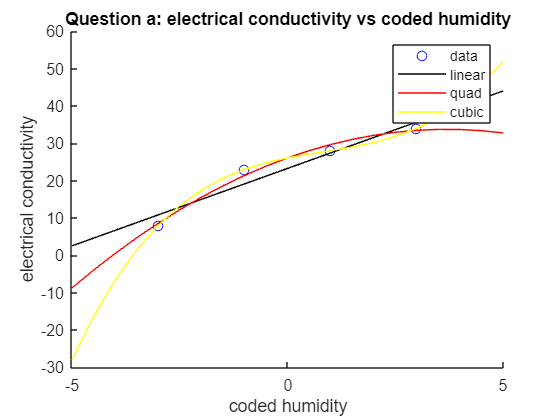

hp = [20 30 40 50];
y = [8 23 28 34];
data_size = 4;
x = (hp-35)/5;
title("Question a: electrical conductivity vs coded humidity")
legend("data","linear", "quad", "cubic")
xlabel("coded humidity")
ylabel("electrical conductivity")


% for linear
A = [];
b = [];
for r = 1:data_size
    A(r,:) = [1, x(r)];
    b(r,:) = [y(r)];
end

x_ls = (A'*A)\(A'*b);
linearX = linspace(-5,5, 21);
linearY = x_ls(1) + linearX*x_ls(2);
scatter(x, y, "blue");
hold on
x_ls

x_ls =    23.2500
    4.1500


plot(linearX,linearY,"black");

% for quadratic
A = [];
b = [];
for r = 1:data_size
    A(r,:) = [1, x(r), x(r)*x(r)];
    b(r,:) = [y(r)];
end

x_ls = (A'*A)\(A'*b);
quadX = linspace(-5,5, 21);
quadY = x_ls(1) + quadX*x_ls(2) + quadX.*quadX*x_ls(3);
x_ls

x_ls =    26.0625
    4.1500
   -0.5625


plot(quadX, quadY,"red");

% for cubic
A = [];
b = [];
for r = 1:data_size
    A(r,:) = [1, x(r), x(r).^2, x(r).^3];
    b(r,:) = [y(r)];
end

x_ls = (A'*A)\(A'*b);
cubeX = linspace(-5,5, 21);
cubeY = x_ls(1) + cubeX*x_ls(2) + cubeX.^2*x_ls(3) + cubeX.^3*x_ls(4);
x_ls

x_ls =    26.0625
    2.2708
   -0.5625
    0.2292


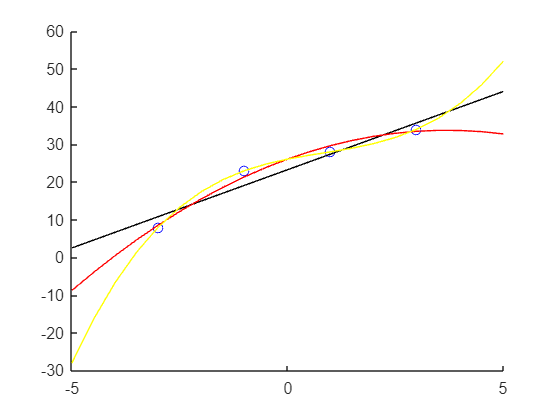

plot(cubeX, cubeY,"yellow");
hold off